% 36.1 - plotting the curve, some unit tangent vectors, etc. 


% TO FIX: 
% axes for plotting, preallocating space w/ zeros


%Using the Matlab Symbolic Toolbox to solve for properties of parametric
%curves
clc, clear all

%For this demo code, we will solve for the parametric circle that is
%presented in Robo Night 1

%First we must define the symbolic variables we will being using
syms B t r d

%Define the equation for the parametric circle. For clarity, I am first 
%creating individual equations for r in the i, j, and k direction, 
%then packing them in one vector. In this case, we are
%creating a 1x3 vector that has symbolic equations for the i, j, and k
%components of the equation, respectively. Note that the k component in
%this case is just equal to 0. We use 0*u because if we substitute a vector
%of numerical values in for the symbolic u at a later time, the dimensions
%of the vector will be consistent.
ri=4*.3960*cos(2.65*(B*t+1.4));
rj=4*(-.99)*sin(B*t+1.4);
rk=0*B*t;
r=[ri,rj,rk];

%to take the derivative, we use the diff function in Matlab, with the
%inputs being diff(function,variable to differentiate)
dr=diff(r,t);

%To find the unit tangent we divide by the magnitude of r'=dr. To make this
%result look nice, we want to add some assumptions
assume(B,{'real','positive'})
assume(t,{'real','positive'})
assume(d,{'real', 'positive'})

%despite these assumptions, you will see that the unit tangent vector is a
%bit difficult to read (note I use the norm function, not abs)
T_hat_ugly=dr./norm(dr)

$$T\_hat\_ugly = \begin{array}{l} \left(\begin{array}{ccc} -\frac{5247\,B\,\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}{1250\,\sigma_{1}} & -\frac{99\,B\,\cos\left(B\,t+\frac{7}{5}\right)}{25\,\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{\frac{9801\,B^{2}\,{\left|\cos\left(B\,t+\frac{7}{5}\right)\right|}^{2}}{625}+\frac{27531009\,B^{2}\,{\left|\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)\right|}^{2}}{1562500}} \end{array}$$

T_hat=simplify(T_hat_ugly)

$$T\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{53\,\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}{\sigma_{1}} & -\frac{50\,\cos\left(B\,t+\frac{7}{5}\right)}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\cos\left(B\,t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}^{2}} \end{array}$$

dT_hat=diff(T_hat,t);
N_hat=dT_hat/norm(dT_hat);
N_hat=simplify(N_hat)

$$N\_hat = \begin{array}{l} \left(\begin{array}{ccc} -\frac{50\,\sigma_{3}}{\sigma_{1}} & \frac{53\,\sigma_{2}}{\sigma_{1}} & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sqrt{2500\,{\sigma_{3}}^{2}+2809\,{\sigma_{2}}^{2}}\\ \sigma_{2}=40\,\sin\left(B\,t+\frac{7}{5}\right)+73\,\sin\left(\frac{43\,B\,t}{10}+\frac{301}{50}\right)+33\,\sin\left(\frac{63\,B\,t}{10}+\frac{441}{50}\right)\\ \sigma_{3}=73\,\cos\left(\frac{13\,B\,t}{20}+\frac{91}{100}\right)+106\,\cos\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)+33\,\cos\left(\frac{93\,B\,t}{20}+\frac{651}{100}\right) \end{array}$$

omega = simplify(cross(T_hat, dT_hat))

$$omega = \left(\begin{array}{ccc} 0 & 0 & -\frac{265\,B\,\left(73\,\cos\left(\frac{33\,B\,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,B\,t}{20}+\frac{511}{100}\right)\right)}{5000\,\cos\left(2\,B\,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+10618} \end{array}\right)$$

speed = simplify(norm(dr));
vL = (2*speed - d*omega)/2;

$$vL = \left(\begin{array}{ccc} -\frac{5247\,B\,\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}{1250} & -\frac{99\,B\,\cos\left(B\,t+\frac{7}{5}\right)}{25} & \frac{265\,B\,d\,\left(73\,\cos\left(\frac{33\,B\,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,B\,t}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,B\,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+10618\right)} \end{array}\right)$$

vR = (2*speed + d*omega)/2;

$$vR = \left(\begin{array}{ccc} -\frac{5247\,B\,\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}{1250} & -\frac{99\,B\,\cos\left(B\,t+\frac{7}{5}\right)}{25} & -\frac{265\,B\,d\,\left(73\,\cos\left(\frac{33\,B\,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,B\,t}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,B\,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+10618\right)} \end{array}\right)$$

1 complete


2 complete


3 complete


4 complete


5 complete


6 complete


7 complete


8 complete


9 complete


10 complete


11 complete


12 complete


13 complete


14 complete


15 complete


16 complete


17 complete


18 complete


19 complete


20 complete


21 complete


22 complete


23 complete


24 complete


25 complete


26 complete


27 complete


28 complete


29 complete


30 complete


31 complete


32 complete


33 complete


34 complete


35 complete


36 complete


37 complete


38 complete


39 complete


40 complete


41 complete


42 complete


43 complete


44 complete


45 complete


46 complete


47 complete


48 complete


49 complete


50 complete


51 complete


52 complete


53 complete


54 complete


55 complete


56 complete


57 complete


58 complete


59 complete


60 complete


61 complete


62 complete


63 complete


64 complete


65 complete


66 complete


67 complete


68 complete


69 complete


70 complete


71 complete


72 complete


73 complete


74 complete


75 complete


76 complete


77 complete


78 complete


79 complete


80 complete


81 complete


82 complete


83 complete


84 complete


85 complete


86 complete


87 complete


88 complete


89 complete


90 complete


91 complete


92 complete


93 complete


94 complete


95 complete


96 complete


97 complete


98 complete


99 complete


100 complete


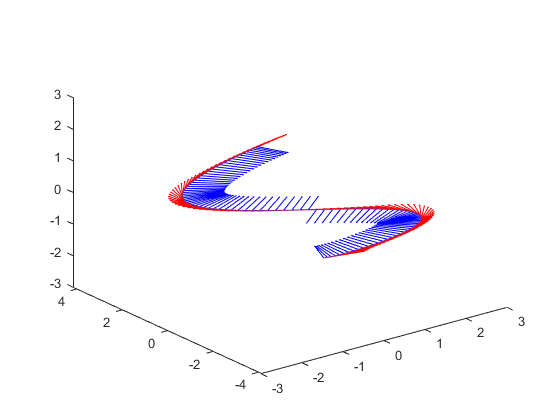

% IN THIS CASE, WE DON'T CARE ABOUT BINORMAL, K, OR TORSION

% %The unit binormal vector is found from the cross product of the unit
% %tangent and unit normal
% B_hat=cross(T_hat,N_hat);
% B_hat=simplify(B_hat)
% 
% %We can also find the curvature
% kappa=norm(dT_hat)/norm(dr);
% kappa=simplify(kappa)
% 
% %How about the Torsion?
% tau=-N_hat*(diff(B_hat,u)/norm(dr))'

%If we wish to visualize this curve, we can make substitutions into our
%functions. 
B_num = 2;% define a specific radius
t_num = linspace(0,.5*pi,100); % define a set of evenly spaced points between 0 and 2*pi
d_num = .235;

%we will also convert to a number of type double

% preallocating size for plots
% r_num = zeros(length(t_num),3)
% T_hat_num = zeros(length(t_num), 3)
% N_hat_num = zeros(length(t_num),3)

for n=1:length(t_num)
%     representing all of what we care about as doubles instead of symbolic
    r_num(n,:)=double(subs(r,[B, t],[B_num, t_num(n)]));
    T_hat_num(n,:)=double(subs(T_hat,[B, t],[B_num, t_num(n)]));
    N_hat_num(n,:)=double(subs(N_hat,[B, t],[B_num, t_num(n)]));
%     B_hat_num(n,:)=double(subs(B_hat,[R, u],[R_num, u_num(n)]));
    disp(n+ " complete")
    
    %we can also plot this using the quiver3 function
    plot3(r_num(:,1),r_num(:,2),r_num(:,3)), axis([-3 3 -3 3 -3 3]),hold on % plot the entire curve
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),T_hat_num(n,1),T_hat_num(n,2),T_hat_num(n,3),'r') % plot the unit tangent
    quiver3(r_num(n,1),r_num(n,2),r_num(n,3),N_hat_num(n,1),N_hat_num(n,2),N_hat_num(n,3),'b') % plot the unit normal
%     quiver3(r_num(n,1),r_num(n,2),r_num(n,3),B_hat_num(n,1),B_hat_num(n,2),B_hat_num(n,3),'g'), hold off % plot the unit binormal
    drawnow % force the graphic to update as it goes
end



vL_num = (zeros(length(t_num),3));
vR_num = (zeros(length(t_num),3));
for n=1:length(t_num)
    vL_num(n,:)=double(subs(vL,[B,d, t,],[B_num,d_num t_num(n)]));
    vR_num(n,:)=double(subs(vR,[B,d, t],[B_num,d_num t_num(n)]));
end


% 36.2
% omega = simplify(cross(T_hat, dT_hat))
% speed = simplify(norm(dr))
speed = simplify(norm(dr))

$$speed = \frac{99\,B\,\sqrt{2500\,{\cos\left(B\,t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}^{2}}}{1250}$$

vL1 = speed - (d*(omega(3)))/2

$$vL1 = \frac{99\,B\,\sqrt{2500\,{\cos\left(B\,t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}^{2}}}{1250}+\frac{265\,B\,d\,\left(73\,\cos\left(\frac{33\,B\,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,B\,t}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,B\,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+10618\right)}$$

vR1 = speed + (d*(omega(3)))/2

$$vR1 = \frac{99\,B\,\sqrt{2500\,{\cos\left(B\,t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}^{2}}}{1250}-\frac{265\,B\,d\,\left(73\,\cos\left(\frac{33\,B\,t}{20}+\frac{231}{100}\right)+33\,\cos\left(\frac{73\,B\,t}{20}+\frac{511}{100}\right)\right)}{2\,\left(5000\,\cos\left(2\,B\,t+\frac{14}{5}\right)-5618\,\cos\left(\frac{53\,B\,t}{10}+\frac{371}{50}\right)+10618\right)}$$

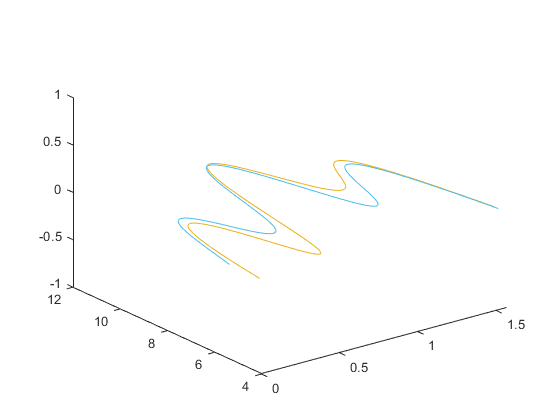

% vL_num = (zeros(length(t_num),3));
% vR_num = (zeros(length(t_num),3));
for n=1:length(t_num)
    vL_num1(n,:)=double(subs(vL1,[B,d, t,],[B_num,d_num t_num(n)]));
    vR_num1(n,:)=double(subs(vR1,[B,d, t],[B_num,d_num t_num(n)]));
    
end
cla
axis auto
plot(t_num, vL_num1)
plot(t_num, vR_num1)

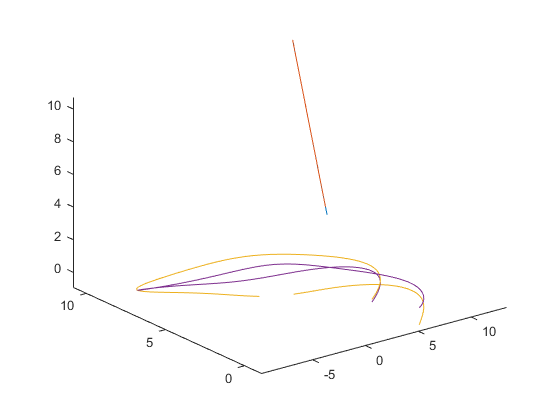

% plot3(vL_num1(:,1), vL_num1(:,2), vL_num1(:,3))
% plot3(vR_num1(:,1), vR_num1(:,2), vR_num1(:,3))


% 36.3
cla % to clear axes
% plot omega and vLin

vLin = (vL1+vR1)/2

$$vLin = \frac{99\,B\,\sqrt{2500\,{\cos\left(B\,t+\frac{7}{5}\right)}^{2}+2809\,{\sin\left(\frac{53\,B\,t}{20}+\frac{371}{100}\right)}^{2}}}{1250}$$

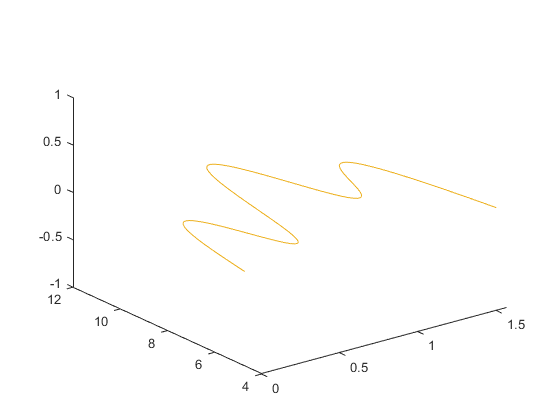

% omega is already defined

for n=1:length(t_num)
    omega_num(n,:)=double(subs(omega,[B, t],[B_num, t_num(n)]));
    vLin_num(n,:)=double(subs(vLin,[B, t],[B_num, t_num(n)]));
    
end 
axis auto
plot(t_num, vLin_num)

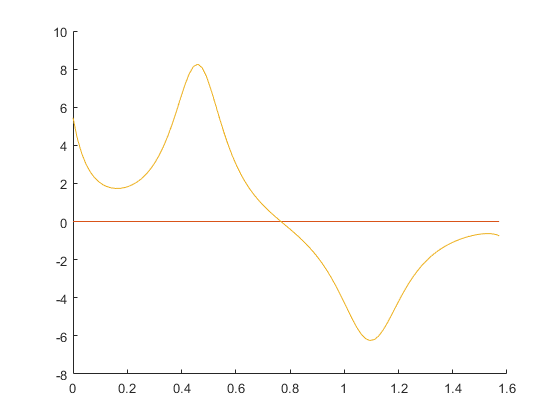

cla
% not sure why my omega plot is like this ....
plot(t_num, omega_num)

% plot robot's estimated path as a function of time using the 

